clearvars

% Init param
M = zeros(12, 1);       % No se utiliza
for i = 1:length(M)
    M(i) = 2^i;
end

N = zeros(20, 1);
for i = 1:length(N)
    N(i) = i;
end

N_fixed = 20; % No se utiliza
[z,w] = GaussHermite_Locations_Weights(N);
M_fixed = 128;
SNR = 1.0;

rho = 0;
max_rho = 1;
delta = 0.001;
% E0_values = [];  % Pel display
% rho_values = []; % Pel display

maxE0 = -Inf;
best_rho = -1; current_rho = 1;

% Per E0(1) - fors
E0_1 = zeros(length(N), 1);
time_E = zeros(length(N), 1);

for i = 1:length(N)
    [x, q]= PAM_generator(M_fixed); % for equiprobable symbols
    [w,z] = GaussHermite_Locations_Weights(N(i));
    tic; % Time starts 
    E0_1(i) = E0(1, N(i), q, x, w, z, SNR);
    elapsed_time = toc; % Time ends
    time_E(i) = elapsed_time;
end

% -------------------------------------------------------------
% Per E0(1) - matrius
E0_1_matrix = zeros(length(N), 1);
time_Ematrix = zeros(length(N), 1);

for i = 1:length(N)
    [x, q]= PAM_generator(M_fixed); % for equiprobable symbols
    [w,z] = GaussHermite_Locations_Weights(N(i));
    [Q, pi_, G] = matrix_generator(N(i), q, x, w, z, SNR);
    tic; % Time starts 
    E0_1_matrix(i) = E0_matrix(Q, pi_, G, 1);
    elapsed_time = toc; % Time ends
    time_Ematrix(i) = elapsed_time;
end

% -------------------------------------------------------------
% Per F0(1) - fors
F0_1 = zeros(length(N), 1);
time_F = zeros(length(N), 1);

for i = 1:length(N)
    [x, q]= PAM_generator(M_fixed); % for equiprobable symbols
    [w,z] = GaussHermite_Locations_Weights(N(i));
    tic; % Time starts 
    F0_1(i) = F0(1, N(i), q, x, w, z, SNR);
    elapsed_time = toc; % Time ends
    time_F(i) = elapsed_time;
end

% -------------------------------------------------------------
% Per F0(1) - matrius
F0_1_matrix = zeros(length(N), 1);
time_Fmatrix = zeros(length(N), 1);

for i = 1:length(N)
    [x, q]= PAM_generator(M_fixed); % for equiprobable symbols
    [w,z] = GaussHermite_Locations_Weights(N(i));
    [Q, pi_, G] = matrix_generator(N(i), q, x, w, z, SNR);
    tic; % Time starts 
    F0_1_matrix(i) = F0_matrix(Q, pi_, G, 1);
    elapsed_time = toc; % Time ends
    time_Fmatrix(i) = elapsed_time;
end

disp("TOT PER M = 128")

TOT PER M = 128


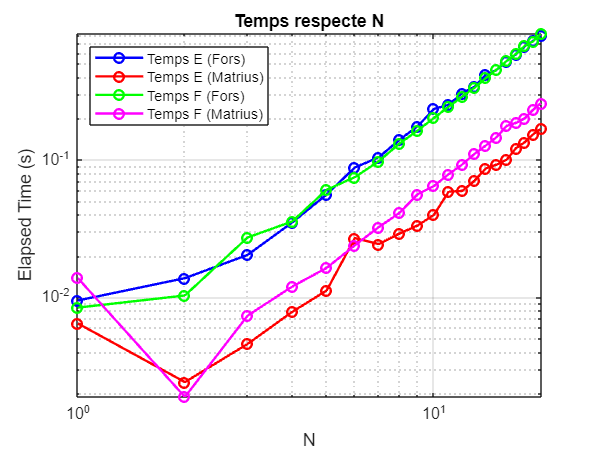

% Display
lim_y = time_E(length(time_E));
if lim_y < time_Ematrix(length(time_Ematrix))
    lim_y = time_Ematrix(length(time_Ematrix));
end
if lim_y < time_F(length(time_F))
    lim_y = time_F(length(time_F));
end
if lim_y < time_Fmatrix(length(time_Fmatrix))
    lim_y = time_Fmatrix(length(time_Fmatrix));
end


% Gràfic
figure;

% Gráfica fors ---- E
loglog(N, time_E, 'o-', 'LineWidth', 1.5, 'Color', 'b', 'DisplayName', 'Temps E (Fors)');

hold on;

% Gráfica matrius ---- E matrix
loglog(N, time_Ematrix, 'o-', 'LineWidth', 1.5, 'Color', 'r', 'DisplayName', 'Temps E (Matrius)');

% Gráfica fors ---- F
loglog(N, time_F, 'o-', 'LineWidth', 1.5, 'Color', 'g', 'DisplayName', 'Temps F (Fors)');

% Gráfica matrius ---- F matrix
loglog(N, time_Fmatrix, 'o-', 'LineWidth', 1.5, 'Color', 'm', 'DisplayName', 'Temps F (Matrius)');

grid on;
xlabel('N');
ylabel('Elapsed Time (s)'); 
title('Temps respecte N');
ylim([0 lim_y]);
xlim([0 N(length(N))]);

% Llegenda
legend('show', 'Location', 'northwest');

hold off;

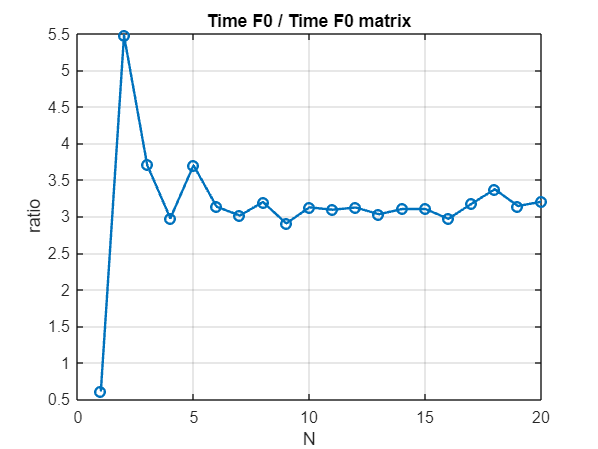

% time F vs time F matrix
r = time_F./time_Fmatrix;
plot(N, r, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('N');
ylabel('ratio'); 
title('Time F0 / Time F0 matrix');
xlim([0 N(length(N))]);

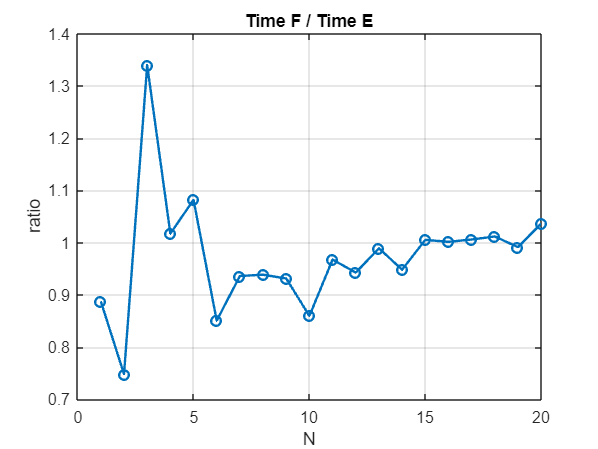


% time E vs time F
r = time_F./time_E;
plot(N, r, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('N');
ylabel('ratio'); 
title('Time F / Time E');
xlim([0 N(length(N))]);

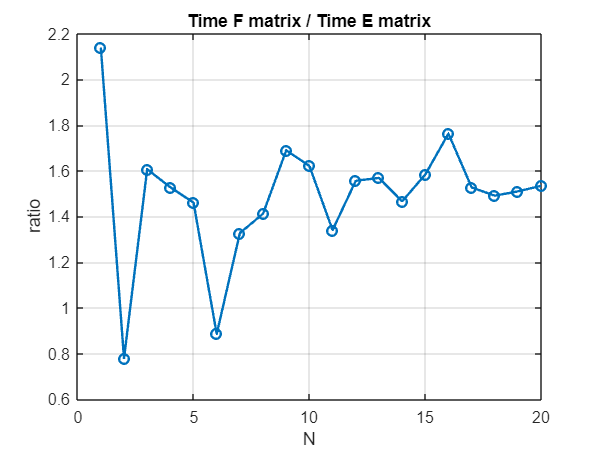


% time E matrix vs time F matrix
r = time_Fmatrix./time_Ematrix;
plot(N, r, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('N');
ylabel('ratio'); 
title('Time F matrix / Time E matrix');
xlim([0 N(length(N))]);

% % Exemple
% [x, q]= PAM_generator(M(2));
% 
% [F0_1, F0p_1, F02p_1] = F0(1, 2, q, x, w, z, SNR)
% E0_1 = 2^(-E0(1, 2, q, x, w, z, SNR));
% E0_1_prima = -F0p_1/(log(2)*F0_1);
% 
% [Q, pi_, G] = matrix_generator(N, q, x, w, z, SNR);
% [F0_1_matriu, F0p_1_matriu, F02p_1_matriu] = F0_matrix(Q, pi_, G, 1)
% E0_1_matriu = E0_matrix(Q, pi_, G, 1);
